# Contents

- Preliminaries

- Network Independant Rates in Distributed Learning

- Robust Asynchronous Stochastic Gradient-Push: Asymptotically Optimal and Network-Independent Performance for Strongly Convex Functions

# 1. Preliminaries

### Kullback-Leibler divergence

the Kullback–Leibler divergence is a measure of how one probability distribution is different from a second. It is the expectation of the logarithmic difference between the probabilities P and Q, where the expectation is taken using the probabilities P. The Kullback–Leibler divergence is defined only if for all x, Q(x)=0 implies P(x)=0 (absolute continuity). Whenever P(x) is zero the contribution of the corresponding term is interpreted as zero

Discrete case


$$D_{\textrm{KL}} \left(P\left|\right|Q\right)=\sum_{i=1}^n P\left(i\right)\ln \frac{P\left(i\right)}{Q\left(i\right)}$$


Continous case


$$D_{\textrm{KL}} \left(P\left|\right|Q\right)=\int_{-\infty \;}^{\infty } p\left(x\right)\ln \frac{p\left(x\right)}{q\left(x\right)}\textrm{dx}$$


P = rand(1,10);
P = P/sum(P);
Q = rand(1,10);
Q = Q/sum(Q);
disp(KLDivergence(P,Q))

    0.4261



#### KL-Divergence for Normal Distributions

found at [https://stats.stackexchange.com/questions/7440/kl-divergence-between-two-univariate-gaussians](https://stats.stackexchange.com/questions/7440/kl-divergence-between-two-univariate-gaussians)


$$D_{\textrm{KL}} \left(N\left(\mu_1 ,\sigma_1 \right)\left|\right|N\left(\mu_2 ,\sigma_2 \right)\right)=\log \frac{\sigma_1 }{\sigma_2 }+\frac{\sigma_1^2 +{\left(\mu_1 -\mu_2 \right)}^2 }{2\sigma_2^2 }-\frac{1}{2}$$


sigma1 = 10*rand();
mu1 = 10*(0.5-rand());
sigma2 = 10*rand();
mu2 = 10*(0.5-rand());
disp(KLDivNorm(sigma1,mu1,sigma2,mu2))

    4.2212



# Network Independant Rates in Distributed Learning

## Problem statement

A group of $n$ agents, $V=\left\lbrace 1,2,\ldotp \ldotp \ldotp ,n\right\rbrace$, each observing realizations of independent processes at each time stemp $k=1,2,\ldotp \ldotp \ldotp$. 

n = 5; % number of agents
k_max = 10; % max time steps

Agent $i$ observes realizations of a sequence of stationary independent, identically distributed random variables $\left\lbrace {S_k }^i \;\right\rbrace$ with unknown distribution $f^i \left(\cdot \right)$. Staking all the random variables at time $k$ generates a single vector ${\mathit{\mathbf{S}}}_{\mathit{\mathbf{k}}}$ distributed as $\mathit{\mathbf{f}}=\prod_{i=1}^n f^i$.

S = zeros(n,k_max); % observed variables
% setting f_i to be gaussian distributions with random parameters
sigma_f = 10*rand(n,1);
mu_f = 20*(0.5-rand(n,1));
for i = 1:n
    S(i,:) = randn(k_max,1)*sigma_f(i)+mu_f(i);
end

The goal is to determine a consensus over $\theta \in \;\Theta$ that parametrizes the distribution $l^i \left(\cdot \left|\theta \;\right.\right)$ refered as beliefs.

% since we know that f_i are gaussians, we set l_i as gaussians too but
% initialized with sigma = 1 and mu = 1
sigma_l = ones(n,1);
mu_l = ones(n,1);

The optimization problem to be solved is:


$$\Theta {\;}^* =\underset{\theta \in \Theta \;}{\textrm{argmax}\;} C\left(\theta \;\right)$$


Where $C\left(\theta \;\right)$ is called *group confidence *on the hypothesis $\theta \;$and is defined as


$$C\left(\theta \;\right)=-D_{\textrm{KL}} \left(\mathit{\mathbf{f}}\left(\cdot \right)\left|\right|\mathit{\mathbf{l}}\left(\cdot \left|\theta \;\right.\right)\right)$$



$$C\left(\theta \;\right)=-\sum_{i=1}^n D_{\textrm{KL}} \left(f^i \left(\cdot \right)\left|\right|l^i \left(\cdot \left|\theta \;\right.\right)\right)$$


Where $D_{\textrm{KL}} \left(\mathit{\mathbf{f}}\left(\cdot \right)\left|\right|l\left(\cdot \left|\theta \;\right.\right)\right)$ is the Kullback-Leibler divergence between the true distribution $S_k^i$ and the probability distribution $l^i \left(\cdot \left|\theta \right.\right)$ that would have been seen by the agents if the hypothesis $\theta \;$ were correct.

C = zeros(k_max,1);
C(1) = 0;
for i = 1:n
    C(1) = C(1) - KLDivNorm(sigma_f(i),mu_f(i),sigma_l(i),mu_l(i)); 
end

The agents interact in a network modeled as a sequence of directed graphs $\left\lbrace G_k \right\rbrace$ that is B-strongly-connected, i.e. there is an integer $B\ge 1$ such that the graph $\left(V,\underset{i=\textrm{kB}}{\bigcup^{\left(k+1\right)B-1} E_i } \right)$ is connected for all $k\ge 0$.

% % option 1, random graph
% G = randi([0 1],n,n,k_max);
% for i = 1:n
%     for j = 1:k_max
%         G(i,i,j) = 1;
%     end
% end
% option 2, cyclic graph (B = n)
G = zeros(n,n,k_max);
for j = 1:k_max
    G(1+mod(j-1,n),1+mod(j,n),j) = 1;
    for i = 1:n
        G(i,i,j) = 1;
    end
end

## Belief Update Rule


$$y_0^i =1$$



$$y_{k+1}^i =\sum_{j\in N_k^i }^{\;} \frac{y_k^j }{d_k^j }$$



$$\mu_{k+1}^i \left(\theta \right)=\frac{1}{Z_{k+1}^i }{\left(\prod_{j\in N_k^i } \mu_k^j {\left(\theta \right)}^{\frac{y_k^j }{d_k^j }} l_k^i \left(s_k^i |\theta \right)\right)}^{\frac{1}{y_{k+1}^i }}$$



$$Z_{k+1}^i =\sum_{p=1}^m {\left(\prod_{j\in N_k^i } \mu_k^j {\left(\theta \right)}^{\frac{y_k^j }{d_k^j }} l_k^i \left(s_k^i |\theta \right)\right)}^{\frac{1}{y_{k+1}^i }}$$


# Robust Asynchronous Stochastic Gradient-Push: Asymptotically Optimal and Network-Independent Performance for Strongly Convex Functions

We assume there are n agents V = {1, . . . , n}, communicating through a fixed directed graph G = (V, E), where E is the set of directed arcs. We assume G does not have self-loops and is strongly connected.

n = 5;
% arbitrary network topology - ring
G = eye(n);
for i=1:n
    G(1+mod(i-1,n),1+mod(i,n)) = 1;
end
% agents initialization
for i = 1:n
    V(i) = Agent(i, n, rand, sum(G(i,:))); %#ok<SAGROW>
end

Each node $i$ helds a vector ${\mathit{\mathbf{x}}}_{\mathit{\mathbf{i}}}$ (in particular $x_i$ can be a scalar) and the target is to achieve consensus over the average of the initial states.

xm = 0;
for i = 1:n
    xm = xm + V(i).x;
end
xm = xm/n;
disp(xm)

    0.7591



## RASP (Robust Asynchonous Sum-Push)

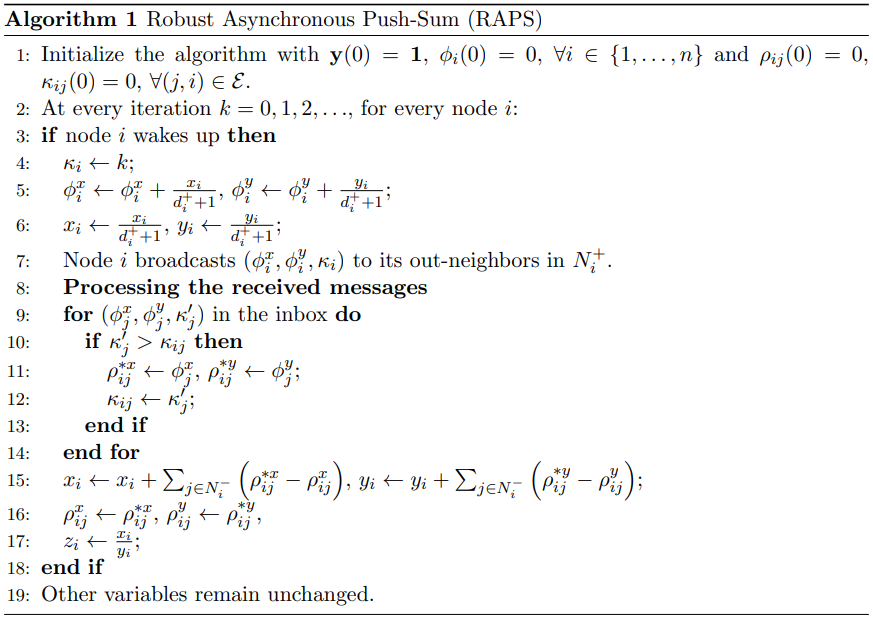

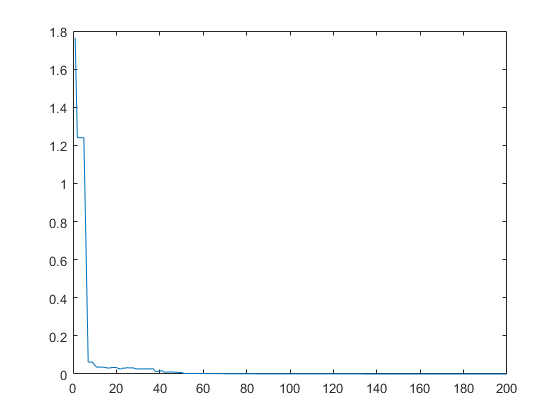

k_max = 200;
wake_prob = 0.25;
loss_prob = 0.10;
C = zeros(k_max,1);
x = zeros(k_max,n);
Y = zeros(k_max,n);
Z = zeros(k_max,n);
PhiX = zeros(k_max,n);
PhiY = zeros(k_max,n);
K = zeros(k_max,n);
for k = 1:k_max
    % actual algorithm
    for i = 1:n
        if(rand<wake_prob)
            V(i).k(i) = k;
            V(i).phix = V(i).phix + V(i).x/(V(i).do+1);
            V(i).phiy = V(i).phiy + V(i).y/(V(i).do+1);
            V(i).x = V(i).x/(V(i).do+1);
            V(i).y = V(i).y/(V(i).do+1);
            for j = 1:n
                if(G(i,j) == 1 && rand > loss_prob)
                    V(j).m_buffer(i,1) = V(i).phix;
                    V(j).m_buffer(i,2) = V(i).phiy;
                    V(j).k(i) = V(i).k(i);
                end
            end
            for j=1:n
                if(G(j,i) == 1)
                    V(i).x = V(i).x + V(i).m_buffer(j,1)-V(i).rhox(j);
                    V(i).y = V(i).y + V(i).m_buffer(j,2)-V(i).rhoy(j);
                    V(i).rhox(j) = V(i).m_buffer(j,1);
                    V(i).rhoy(j) = V(i).m_buffer(j,2);
                    V(i).z = V(i).x/V(i).y;
                end
            end
        end
    end
    % visualization
    for i = 1:n
        C(k) = C(k) + (V(i).z-xm)^2;
        X(k,i) = V(i).x; %#ok<SAGROW> 
        Y(k,i) = V(i).y;
        Z(k,i) = V(i).z;
        PhiX(k,i) = V(i).phix;
        PhiY(k,i) = V(i).phiy;
        K(k,i) = V(i).k(i);
    end
end
figure(1)
plot(C)

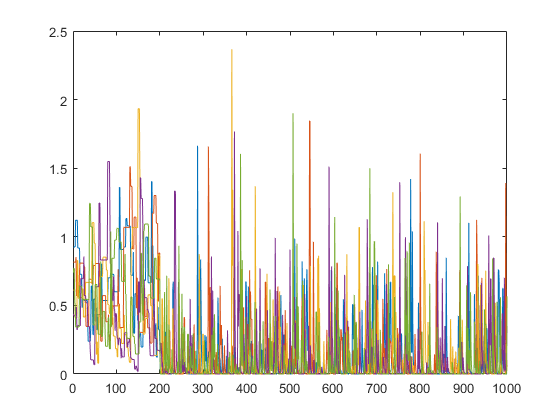

figure(2)
plot(X)

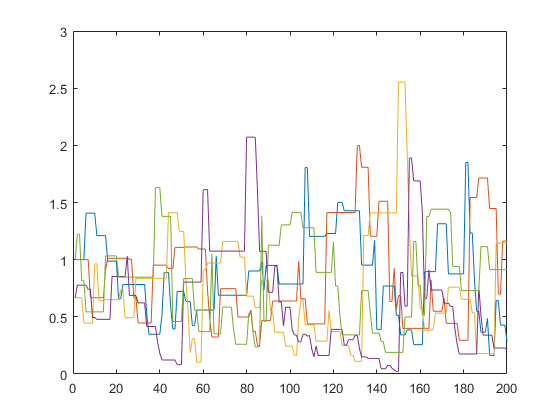

figure(3)
plot(Y)

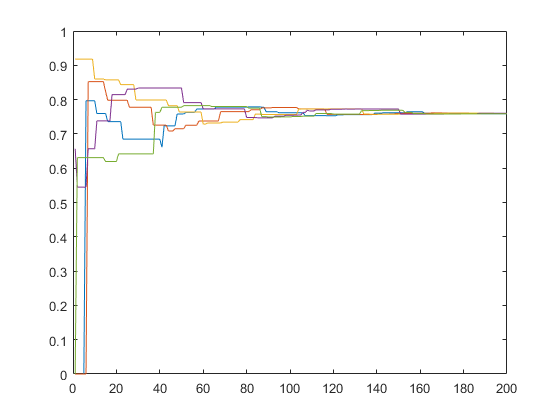

figure(4)
plot(Z)

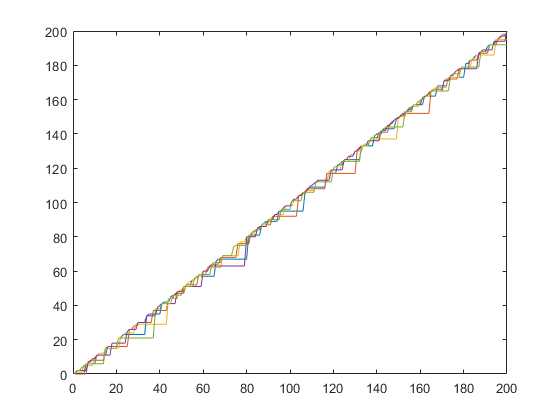

figure(5)
plot(K)

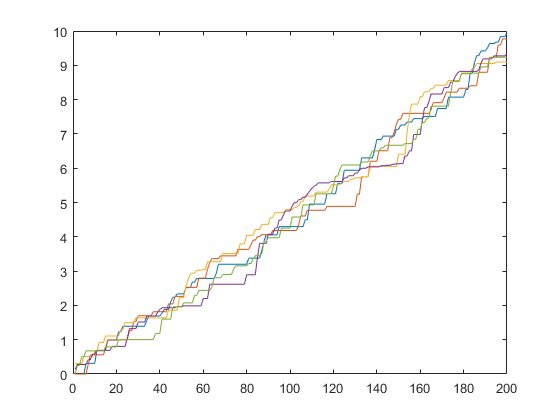

figure(6)
plot(PhiX)

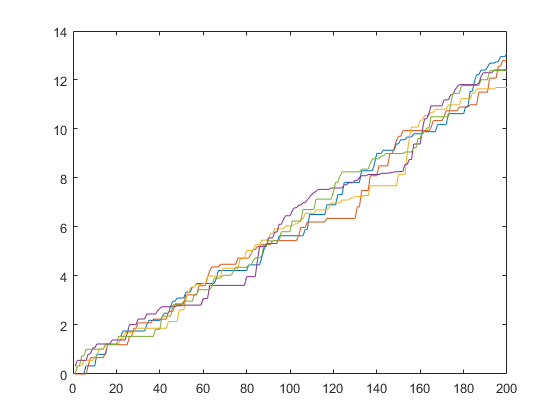

figure(6)
plot(PhiY)